# Partie 1 - Modélisation du système

clc; clear; close all;
syms z;
syms z_p;
syms n_tubes;
syms n_bonbonne;
syms u_bonbonne;
syms u_tubes;

syms capacite_bonbonne;
syms m_bonbonne_vide;
syms p_bonbonne_pleine;
syms m_equipement;
syms h_bonbonne;
syms r_bonbonne;
syms r_tubes_int;
syms r_tubes_ext;
syms h_tubes;
syms e_bouchon;
syms h_plomb;

syms rho_eau;
syms rho_air;
syms rho_PVC;
syms rho_plomb;
syms R;
syms g;
syms P_0;
syms T;
syms M_air;


valeurs = struct(...
    ... % Constantes universelles
    'g', 9.81, ...                  
    'rho_eau', 1000, ...
    'rho_air', 1.293, ...
    'rho_PVC', 1400, ...
    'rho_plomb', 11350, ...
    'R', 8.31446261815324, ...
    'P_0', 101300, ...
    'T', 293.15, ...
    'M_air', 28.965338/1000, ...
    ...
    'capacite_bonbonne', 10 * 1e-3,...
    'm_bonbonne_vide', 10, ...
    'p_bonbonne_pleine', 232 * 1e5, ...
    'm_equipement', 2.5, ...
    'h_bonbonne', 0.8,...
    'r_bonbonne', 0.19/2,...
    'r_tubes_int', 0.145/2, ...
    'r_tubes_ext', 0.168/2,...
    'h_tubes', 0.312, ...
    'e_bouchon', 0.012);

valeurs_calculees = struct();

## Calcul pour les tubes

### Volume du tube (Volume extérieur - Volume intérieur + Volume Bouchon)

V_cavite_init = (pi * h_tubes * r_tubes_int^2) - (pi * e_bouchon * r_tubes_int^2);
valeurs_calculees.V_cavite_init = double(subs(V_cavite_init, valeurs));

V_Tube = (pi * h_tubes * r_tubes_ext^2) - V_cavite_init;
valeurs_calculees.V_Tube = double(subs(V_Tube, valeurs));

V_cavite_init, valeurs_calculees.V_cavite_init, V_Tube, valeurs_calculees.V_Tube

$$V\_cavite\_init = \pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}-\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}$$

ans = 0.0050

$$V\_Tube = \pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}-\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{ext}}}^{2}$$

ans = 0.0020

### Masse du tube + bouchon

m_tube = V_Tube * rho_PVC;
valeurs_calculees.m_tube = double(subs(m_tube, valeurs));

m_tube, valeurs_calculees.m_tube

$$m\_tube = \rho_{\mathrm{PVC}}\,\left(\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}-\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{ext}}}^{2}\right)$$

ans = 2.7471

### Quantité air initiale

n_tubes_init = 3 * P_0 * V_cavite_init / (R * T);
valeurs_calculees.n_tubes_init = double(subs(n_tubes_init, valeurs));

n_tubes_init, valeurs_calculees.n_tubes_init

$$n\_tubes\_init = -\frac{3\,P_{0}\,\left(\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}-\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}\right)}{R\,T}$$

ans = 0.6177

### Masse air tube

m_air_tubes = n_tubes * M_air;
m_air_tubes_init = subs(m_air_tubes, n_tubes=n_tubes_init);

valeurs_calculees.m_air_tubes_init = double(subs(m_air_tubes_init, valeurs));

m_air_tubes, m_air_tubes_init, valeurs_calculees.m_air_tubes_init

$$m\_air\_tubes = M_{\mathrm{air}}\,n_{\mathrm{tubes}}$$

$$m\_air\_tubes\_init = -\frac{3\,M_{\mathrm{air}}\,P_{0}\,\left(\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}-\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}\right)}{R\,T}$$

ans = 0.0179

## Bonbonne

### Volume

V_bonbonne_ext = pi * h_bonbonne * r_bonbonne^2;
valeurs_calculees.V_bonbonne_ext = double(subs(V_bonbonne_ext, valeurs));

V_bonbonne_ext, valeurs_calculees.V_bonbonne_ext

$$V\_bonbonne\_ext = \pi \,h_{\mathrm{bonbonne}}\,{r_{\mathrm{bonbonne}}}^{2}$$

ans = 0.0227

### Masse bonbonne + equipement

m_bonbonne_vide_equipement = m_bonbonne_vide + m_equipement;
valeurs_calculees.m_bonbonne_vide_equipement = double(subs(m_bonbonne_vide_equipement, valeurs));

m_bonbonne_vide_equipement, valeurs_calculees.m_bonbonne_vide_equipement

$$m\_bonbonne\_vide\_equipement = m_{\mathrm{bonbonne},\mathrm{vide}}+m_{\mathrm{equipement}}$$

ans = 12.5000

### Quantite air

n_bonbonne_init = p_bonbonne_pleine * capacite_bonbonne / (R * T);
valeurs_calculees.n_bonbonne_init = double(subs(n_bonbonne_init , valeurs));

n_bonbonne_init, valeurs_calculees.n_bonbonne_init

$$n\_bonbonne\_init = \frac{{\mathrm{capacite}}_{\mathrm{bonbonne}}\,p_{\mathrm{bonbonne},\mathrm{pleine}}}{R\,T}$$

ans = 95.1840

### Masse air bonbonne initiale

m_air_bonbonne = M_air * n_bonbonne;
m_air_bonbonne_init = subs(m_air_bonbonne, n_bonbonne = n_bonbonne_init);
valeurs_calculees.m_air_bonbonne_init = double(subs(m_air_bonbonne_init, valeurs));

m_air_bonbonne, m_air_bonbonne_init, valeurs_calculees.m_air_bonbonne_init

$$m\_air\_bonbonne = M_{\mathrm{air}}\,n_{\mathrm{bonbonne}}$$

$$m\_air\_bonbonne\_init = \frac{M_{\mathrm{air}}\,{\mathrm{capacite}}_{\mathrm{bonbonne}}\,p_{\mathrm{bonbonne},\mathrm{pleine}}}{R\,T}$$

ans = 2.7570

## Fusion

### Masse totale

#### Masse statique

m_static = m_bonbonne_vide_equipement + 3 * m_tube;
valeurs_calculees.m_static = double(subs(m_static, valeurs));

m_static, valeurs_calculees.m_static

$$m\_static = m_{\mathrm{bonbonne},\mathrm{vide}}+m_{\mathrm{equipement}}+3\,\rho_{\mathrm{PVC}}\,\left(\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}-\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{ext}}}^{2}\right)$$

ans = 20.7414

#### Masse variable

m_variable = m_air_bonbonne + 3 *  m_air_tubes;
m_variable_init = m_air_bonbonne_init + 3 * m_air_tubes_init;
valeurs_calculees.m_variable = double(subs(m_variable_init, valeurs));

m_variable, m_variable_init, valeurs_calculees.m_variable

$$m\_variable = M_{\mathrm{air}}\,n_{\mathrm{bonbonne}}+3\,M_{\mathrm{air}}\,n_{\mathrm{tubes}}$$

$$m\_variable\_init = \frac{M_{\mathrm{air}}\,{\mathrm{capacite}}_{\mathrm{bonbonne}}\,p_{\mathrm{bonbonne},\mathrm{pleine}}}{R\,T}-\frac{9\,M_{\mathrm{air}}\,P_{0}\,\left(\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}-\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}\right)}{R\,T}$$

ans = 2.8107

#### Masse totale

m_totale = m_static + m_variable;
m_totale_init = m_static + m_variable_init;
valeurs_calculees.m_totale = double(subs(m_totale_init, valeurs));

m_totale, valeurs_calculees.m_totale

$$m\_totale = m_{\mathrm{bonbonne},\mathrm{vide}}+m_{\mathrm{equipement}}+M_{\mathrm{air}}\,n_{\mathrm{bonbonne}}+3\,M_{\mathrm{air}}\,n_{\mathrm{tubes}}+3\,\rho_{\mathrm{PVC}}\,\left(\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}-\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{ext}}}^{2}\right)$$

ans = 23.5521

### Volume

#### Volume statique

V_static = V_bonbonne_ext + 3 * V_Tube;
valeurs_calculees.V_static = double(subs(V_static, valeurs));
V_static, valeurs_calculees.V_static

$$V\_static = 3\,\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+\pi \,h_{\mathrm{bonbonne}}\,{r_{\mathrm{bonbonne}}}^{2}-3\,\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+3\,\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{ext}}}^{2}$$

ans = 0.0286

#### Volume variable

V_variable = (n_tubes * R * T) / (P_0 + rho_eau * g * -z);
V_variable_init = subs(V_variable, [n_tubes, z], [n_tubes_init, 0]);

assert(V_variable_init == 3 * V_cavite_init, "Erreur dans la calcul du volume variable");

valeurs_calculees.V_variable_init = double(subs(V_variable_init, valeurs));
V_variable_init, valeurs_calculees.V_variable_init

$$V\_variable\_init = 3\,\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}-3\,\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}$$

ans = 0.0149

#### Volume total

V_total = V_static + V_variable;
V_total_init = subs(V_total, [n_tubes, n_bonbonne, z], [n_tubes_init, n_bonbonne_init, 0]);

assert(V_total_init == V_variable_init + V_static, "Erreur dans le calcul du volume sans plomb");

valeurs_calculees.V_total_init = double(subs(V_total_init, valeurs));
V_total_init, valeurs_calculees.V_total_init

$$V\_total\_init = h_{\mathrm{bonbonne}}\,\pi \,{r_{\mathrm{bonbonne}}}^{2}+3\,h_{\mathrm{tubes}}\,\pi \,{r_{\mathrm{tubes},\mathrm{ext}}}^{2}$$

ans = 0.0434

## Calcul de l'équilibre de flotabilité neutre à 0m

V_plomb = h_plomb * pi * r_bonbonne^2;
m_plomb = rho_plomb * V_plomb;

eq_plomb = rho_eau * g * V_total_init - g * m_totale_init + V_plomb * rho_eau * g == m_plomb * g;
s_plomb = solve(eq_plomb, h_plomb);

valeurs_calculees.s_plomb = double(subs(s_plomb, valeurs));
valeurs.h_plomb = valeurs_calculees.s_plomb;

s_plomb, valeurs_calculees.s_plomb

$$s\_plomb = \begin{array}{l} \frac{g\,\left(m_{\mathrm{bonbonne},\mathrm{vide}}+m_{\mathrm{equipement}}+3\,\rho_{\mathrm{PVC}}\,\left(\sigma_{2}-\sigma_{1}+\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{ext}}}^{2}\right)-\frac{9\,M_{\mathrm{air}}\,P_{0}\,\left(\sigma_{2}-\sigma_{1}\right)}{R\,T}+\frac{M_{\mathrm{air}}\,{\mathrm{capacite}}_{\mathrm{bonbonne}}\,p_{\mathrm{bonbonne},\mathrm{pleine}}}{R\,T}\right)-g\,\rho_{\mathrm{eau}}\,\left(h_{\mathrm{bonbonne}}\,\pi \,{r_{\mathrm{bonbonne}}}^{2}+3\,h_{\mathrm{tubes}}\,\pi \,{r_{\mathrm{tubes},\mathrm{ext}}}^{2}\right)}{\pi \,g\,{r_{\mathrm{bonbonne}}}^{2}\,\rho_{\mathrm{eau}}-\pi \,g\,{r_{\mathrm{bonbonne}}}^{2}\,\rho_{\mathrm{plomb}}}\\ \mathrm{where}\\ \sigma_{1}=\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}\\ \sigma_{2}=\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2} \end{array}$$

ans = 0.0677

## Masse statique après équilibrage avec le plomb

m_static_finale = m_static + m_plomb;
valeurs_calculees.m_static_finale = double(subs(subs(m_static_finale, valeurs), h_plomb=valeurs_calculees.s_plomb));

m_totale_finale = m_static_finale + m_variable;

m_static_finale, valeurs_calculees.m_static_finale

$$m\_static\_finale = h_{\mathrm{plomb}}\,\rho_{\mathrm{plomb}}\,\pi \,{r_{\mathrm{bonbonne}}}^{2}+m_{\mathrm{bonbonne},\mathrm{vide}}+m_{\mathrm{equipement}}+3\,\rho_{\mathrm{PVC}}\,\left(\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}-\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{ext}}}^{2}\right)$$

ans = 42.5406

## Volume statique après équilibrage avec le plomb

V_static_final = V_static + V_plomb;
valeurs_calculees.V_static_final = double(subs(subs(V_static_final, valeurs), h_plomb=valeurs_calculees.s_plomb));

V_total_final = V_static_final + V_variable;

V_static_final, valeurs_calculees.V_static_final

$$V\_static\_final = 3\,\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+\pi \,h_{\mathrm{bonbonne}}\,{r_{\mathrm{bonbonne}}}^{2}+\pi \,h_{\mathrm{plomb}}\,{r_{\mathrm{bonbonne}}}^{2}-3\,\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+3\,\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{ext}}}^{2}$$

ans = 0.0305

# Partie 2 - Analyse du système en BO

## 2.1 - Expressions communes

Calcul de la pression dans les tubes

P_1 = P_0 + rho_eau * g * (-z + e_bouchon);
P_tube = 1/2 * (P_1 + sqrt( (P_1^(2) + 4 * rho_eau * g * n_tubes * R * T / (3 * pi * r_tubes_int^2)) ))

$$P\_tube = \frac{P_{0}}{2}+\frac{\sqrt{{\left(P_{0}+g\,\rho_{\mathrm{eau}}\,\left(e_{\mathrm{bouchon}}-z\right)\right)}^{2}+\frac{4\,R\,T\,g\,n_{\mathrm{tubes}}\,\rho_{\mathrm{eau}}}{3\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}\,\pi }}}{2}+\frac{g\,\rho_{\mathrm{eau}}\,\left(e_{\mathrm{bouchon}}-z\right)}{2}$$

## 2.2 - Position d'équilibre

### 2.2.1 - Position d'équilibre, n_tube dépendant de n_bonbonne

eq_equilibre_2m = rho_eau * V_total_final == m_totale_finale;
s_equilibre_2m = solve(eq_equilibre_2m, n_tubes)

$$s\_equilibre\_2m = -\frac{m_{\mathrm{bonbonne},\mathrm{vide}}+m_{\mathrm{equipement}}+M_{\mathrm{air}}\,n_{\mathrm{bonbonne}}-\rho_{\mathrm{eau}}\,\left(3\,\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+\pi \,h_{\mathrm{bonbonne}}\,{r_{\mathrm{bonbonne}}}^{2}+\pi \,h_{\mathrm{plomb}}\,{r_{\mathrm{bonbonne}}}^{2}-3\,\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+3\,\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{ext}}}^{2}\right)+3\,\rho_{\mathrm{PVC}}\,\left(\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}-\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{ext}}}^{2}\right)+\pi \,h_{\mathrm{plomb}}\,{r_{\mathrm{bonbonne}}}^{2}\,\rho_{\mathrm{plomb}}}{3\,M_{\mathrm{air}}-\frac{R\,T\,\rho_{\mathrm{eau}}}{P_{0}-g\,\rho_{\mathrm{eau}}\,z}}$$

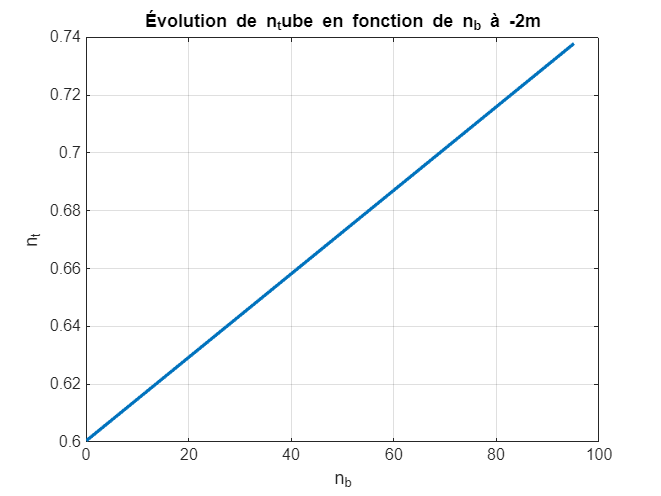

function tracer_nt_en_fct_nb(s_equilibre_2m, valeurs, n_bonbonne_init)
    syms z;
    AN_n_bonbonne = subs(subs(s_equilibre_2m, z, -2), valeurs);
    n_b_vals = linspace(0, double(subs(n_bonbonne_init, valeurs)), 5);
    AN_vals = zeros(size(n_b_vals));

    for i = 1:length(n_b_vals)
        AN_vals(i) = double(subs(subs(AN_n_bonbonne, 'n_bonbonne', n_b_vals(i)), valeurs));
    end

    plot(n_b_vals, AN_vals, 'LineWidth', 2);
    xlabel('n_b');
    ylabel('n_t');
    title('Évolution de n_tube en fonction de n_b à -2m');
    grid on;
    hold off;
end

tracer_nt_en_fct_nb(s_equilibre_2m, valeurs, n_bonbonne_init);

### 2.2.2 - Calcul de la position d'équilibre sans perte d'air

eq_ss_pertes = rho_eau * V_total_final == m_static_finale + M_air * (n_bonbonne_init + n_tubes_init);
s_ss_pertes = solve(eq_ss_pertes, n_tubes);

valeurs_calculees.s_ss_pertes = double(subs(subs(s_ss_pertes, z, -2), valeurs));
valeurs_calculees.n_tubes_2m = valeurs_calculees.s_ss_pertes;
valeurs_calculees.n_bonbonne_2m = double(subs(subs(n_bonbonne_init + n_tubes_init, z, -2), valeurs)) - valeurs_calculees.n_tubes_2m;

s_ss_pertes, valeurs_calculees.s_ss_pertes, valeurs_calculees.n_bonbonne_2m

$$s\_ss\_pertes = \begin{array}{l} \frac{\left(P_{0}-g\,\rho_{\mathrm{eau}}\,z\right)\,\left(m_{\mathrm{bonbonne},\mathrm{vide}}+m_{\mathrm{equipement}}-\rho_{\mathrm{eau}}\,\left(3\,\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+\pi \,h_{\mathrm{bonbonne}}\,{r_{\mathrm{bonbonne}}}^{2}+\pi \,h_{\mathrm{plomb}}\,{r_{\mathrm{bonbonne}}}^{2}-3\,\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+3\,\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{ext}}}^{2}\right)-M_{\mathrm{air}}\,\left(\frac{3\,P_{0}\,\left(\sigma_{2}-\sigma_{1}\right)}{R\,T}-\frac{{\mathrm{capacite}}_{\mathrm{bonbonne}}\,p_{\mathrm{bonbonne},\mathrm{pleine}}}{R\,T}\right)+3\,\rho_{\mathrm{PVC}}\,\left(\sigma_{2}-\sigma_{1}+\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{ext}}}^{2}\right)+\pi \,h_{\mathrm{plomb}}\,{r_{\mathrm{bonbonne}}}^{2}\,\rho_{\mathrm{plomb}}\right)}{R\,T\,\rho_{\mathrm{eau}}}\\ \mathrm{where}\\ \sigma_{1}=\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}\\ \sigma_{2}=\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2} \end{array}$$

ans = 0.7355

ans = 95.0661

## 2.3 - Linéarisation du système

### 2.3.1 - Equations


$$\dot{z}$$


f1 = z_p

$$f1 = z_{p}$$


$$\ddot{z}$$


f2 = g * (rho_eau * V_total_final / m_totale_finale - 1)

$$f2 = g\,\left(\frac{\rho_{\mathrm{eau}}\,\left(3\,\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+\pi \,h_{\mathrm{bonbonne}}\,{r_{\mathrm{bonbonne}}}^{2}+\pi \,h_{\mathrm{plomb}}\,{r_{\mathrm{bonbonne}}}^{2}-3\,\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+3\,\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{ext}}}^{2}+\frac{R\,T\,n_{\mathrm{tubes}}}{P_{0}-g\,\rho_{\mathrm{eau}}\,z}\right)}{h_{\mathrm{plomb}}\,\rho_{\mathrm{plomb}}\,\pi \,{r_{\mathrm{bonbonne}}}^{2}+m_{\mathrm{bonbonne},\mathrm{vide}}+m_{\mathrm{equipement}}+M_{\mathrm{air}}\,n_{\mathrm{bonbonne}}+3\,M_{\mathrm{air}}\,n_{\mathrm{tubes}}+3\,\rho_{\mathrm{PVC}}\,\left(\pi \,e_{\mathrm{bouchon}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}-\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}+\pi \,h_{\mathrm{tubes}}\,{r_{\mathrm{tubes},\mathrm{ext}}}^{2}\right)}-1\right)$$


$$\dot{n_b}$$


f3 = -0.0002 * u_bonbonne * sqrt( n_bonbonne * R * T / capacite_bonbonne - P_tube) 

$$f3 = -\frac{u_{\mathrm{bonbonne}}\,\sqrt{\frac{R\,T\,n_{\mathrm{bonbonne}}}{{\mathrm{capacite}}_{\mathrm{bonbonne}}}-\frac{\sqrt{{\left(P_{0}+g\,\rho_{\mathrm{eau}}\,\left(e_{\mathrm{bouchon}}-z\right)\right)}^{2}+\frac{4\,R\,T\,g\,n_{\mathrm{tubes}}\,\rho_{\mathrm{eau}}}{3\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}\,\pi }}}{2}-\frac{g\,\rho_{\mathrm{eau}}\,\left(e_{\mathrm{bouchon}}-z\right)}{2}-\frac{P_{0}}{2}}}{5000}$$

f4 =  - f3 - 0.0002 * u_tubes * sqrt(P_tube - (P_0 + rho_eau * g * -z))

$$f4 = \begin{array}{l} \frac{u_{\mathrm{bonbonne}}\,\sqrt{\frac{R\,T\,n_{\mathrm{bonbonne}}}{{\mathrm{capacite}}_{\mathrm{bonbonne}}}-\sigma_{1}-\frac{g\,\rho_{\mathrm{eau}}\,\left(e_{\mathrm{bouchon}}-z\right)}{2}-\frac{P_{0}}{2}}}{5000}-\frac{u_{\mathrm{tubes}}\,\sqrt{\sigma_{1}-\frac{P_{0}}{2}+g\,\rho_{\mathrm{eau}}\,z+\frac{g\,\rho_{\mathrm{eau}}\,\left(e_{\mathrm{bouchon}}-z\right)}{2}}}{5000}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{{\left(P_{0}+g\,\rho_{\mathrm{eau}}\,\left(e_{\mathrm{bouchon}}-z\right)\right)}^{2}+\frac{4\,R\,T\,g\,n_{\mathrm{tubes}}\,\rho_{\mathrm{eau}}}{3\,{r_{\mathrm{tubes},\mathrm{int}}}^{2}\,\pi }}}{2} \end{array}$$

### 2.3.2 - A.N. : Calcul de A

F = [f1; f2; f3; f4];
X = [z; z_p; n_bonbonne; n_tubes];

J_A = jacobian(F, X);
valeurs_calculees.A = double(subs( ...
    subs(J_A, valeurs), ...
    {z, n_bonbonne, n_tubes, u_bonbonne, u_tubes}, ...
    {-2, valeurs_calculees.n_bonbonne_2m, valeurs_calculees.n_tubes_2m, 0, 0} ...
    ));
VP_A = eig(valeurs_calculees.A);
vpa(valeurs_calculees.A, 4), vpa(VP_A, 4)

$$ans = \left(\begin{array}{cccc} 0 & 1.0 & 0 & 0\\ 0.2601 & 0 & -0.006259 & 4.341\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$ans = \left(\begin{array}{c} 0.51\\ -0.51\\ 0\\ 0 \end{array}\right)$$

### 2.3.3 - A. N : Calcul de la matrice B

F_B = [f1; f2; f3; f4];
X_B = [u_bonbonne ; u_tubes];

J_B = jacobian(F_B, X_B);

valeurs_calculees.B = double(subs( ...
    subs( ...
        J_B, valeurs ...
    ), ...
    {z, n_bonbonne, n_tubes, u_bonbonne, u_tubes}, ...
    {-2, valeurs_calculees.n_bonbonne_2m, valeurs_calculees.n_tubes_2m, 0, 0} ...
    ));
vpa(valeurs_calculees.B, 3)

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ -0.96 & 0\\ 0.96 & -0.0109 \end{array}\right)$$

### 2.3.4 - Commandabilité

rank(ctrb(valeurs_calculees.A, valeurs_calculees.B))

ans = 4

## 2.4 - Methode LQR

### 2.4.1 - Variables

syms ts1 ts2 ts3 ts4;
syms x1m x2m x3m x4m;
syms u1m u2m rho_commande;

profondeur_max      = 10;                            % m
vitesse_max         = 0.05;                          % m/s

nb_mol_max_bonbonne = double(subs(n_bonbonne_init, valeurs));
nb_mol_max_tubes    = double(subs(3 * (pi * h_tubes * r_tubes_int^2) * (P_0 + rho_eau * g * profondeur_max)  / (R * T), valeurs));

contraintes = struct( ...
    'ts1', 4, ...                   % secondes
    'ts2', 2, ...                   % secondes
    'ts3', 1, ...
    'ts4', 1, ...
    ...
    'x1m', profondeur_max, ...      % m
    'x2m', vitesse_max, ...         % m/s
    'x3m', nb_mol_max_bonbonne, ... % mol
    'x4m', nb_mol_max_tubes, ...    % mol
    'u1m', 1, ...
    'u2m', 1, ...
    'rho_commande', 2)

contraintes = struct with fields:
             ts1: 4
             ts2: 2
             ts3: 1
             ts4: 1
             x1m: 10
             x2m: 0.0500
             x3m: 95.1840
             x4m: 1.2645
             u1m: 1
             u2m: 1
    rho_commande: 2


### 2.4.1 - Matrice Q

q1 = 1 / (ts1 * x1m^2);
q2 = 1 / (ts2 * x2m^2);
q3 = 1 / (ts3 * x3m^2);
q4 = 1 / (ts4 * x4m^2);

Q = diag([2000 1000 q3 q4]);

### 2.4.2 - Matrice R

r1 = 1/u1m^2;
r2 = 1/u2m^2;

N = rho_commande * diag([r1 r2]);

### 2.4.3 - A.N.

valeurs_calculees.LQR_Q = double(subs(Q, contraintes));
vpa(valeurs_calculees.LQR_Q, 4)

$$ans = \left(\begin{array}{cccc} 2000.0 & 0 & 0 & 0\\ 0 & 1000.0 & 0 & 0\\ 0 & 0 & 0.0001104 & 0\\ 0 & 0 & 0 & 0.6255 \end{array}\right)$$

valeurs_calculees.LQR_N = double(subs(N, contraintes));
vpa(valeurs_calculees.LQR_N, 4)

$$ans = \left(\begin{array}{cc} 2.0 & 0\\ 0 & 2.0 \end{array}\right)$$

[K, P, E] = lqr(valeurs_calculees.A, ...
    valeurs_calculees.B, ...
    valeurs_calculees.LQR_Q, ...
    valeurs_calculees.LQR_N)

K =    32.5577   27.0385   -0.0226   15.6334
   -0.3699   -0.3072   -0.0072   -0.1851


P = 1.0e+03 *

    1.7142    0.2312   -0.0001    0.0677
    0.2312    0.1792   -0.0001    0.0562
   -0.0001   -0.0001    0.0014    0.0013
    0.0677    0.0562    0.0013    0.0339


E =   -0.0001 + 0.0000i
  -1.4140 + 0.0000i
  -6.8100 + 6.8536i
  -6.8100 - 6.8536i
